load('bh_SAVED_LIN_PLANT.mat')
size(my_LIN_PLANT)

State-space model with 3 outputs, 4 inputs, and 18 states.


Look at the A maytix:

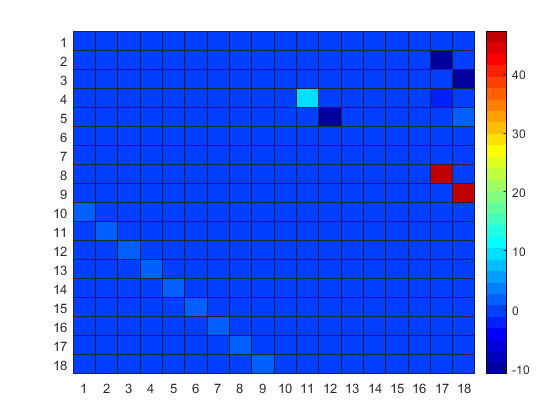

figure;
heatmap(my_LIN_PLANT.A,'Colormap', jet(30))

## Exploring Controllability:

Our current linearised plant has the following shape:

size(my_LIN_PLANT)

State-space model with 3 outputs, 4 inputs, and 18 states.


Let's explore either BALANCING or REDUCING this linear system

%NEW_LIN_PLANT = my_LIN_PLANT;
%[NEW_LIN_PLANT,g,T,Ti] = balreal(my_LIN_PLANT);
[NEW_LIN_PLANT, U_T_mat] = minreal(my_LIN_PLANT);

2 states removed.


The NEW system shape is:

size(NEW_LIN_PLANT)

State-space model with 3 outputs, 4 inputs, and 16 states.


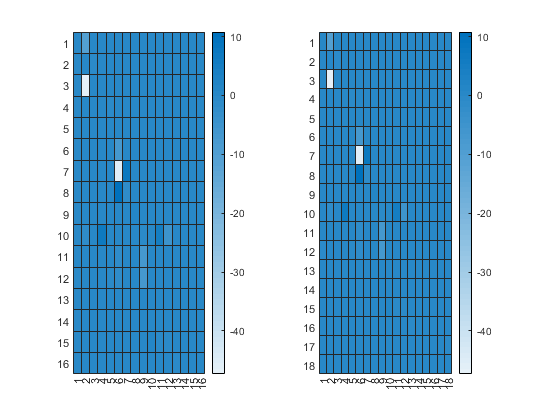

A = NEW_LIN_PLANT.A;
B = NEW_LIN_PLANT.B;
C = NEW_LIN_PLANT.C;
D = NEW_LIN_PLANT.D;

A2 = U_T_mat * my_LIN_PLANT.A *U_T_mat';
B2 = U_T_mat * my_LIN_PLANT.B;
C2 = my_LIN_PLANT.C*U_T_mat';
D2 = D;

M = {A, A2};
figure
subplot(1,2,1); heatmap(M{1});
subplot(1,2,2); heatmap(M{2});